**Task 2: Numerical approximations of **$\mathbb{E}[Q(u)]$

`1.Richardson Extrapolation`

We want to estimate the bias, i.e.

                        
$$Q(u_h)-Q(u) = a_1h^p + \mathcal{O}(h^r)$$


for some $r>p$. Using Richardson extrapolation, we can obtain an approximation of the bias that is $r^{\text{th}}$-order accurate. For example

            (I)     $Q(u_h) - Q(u) = a_1h^p + a_2h^r+\text{h.o.t.}$

           (II)     $Q(u_{h/2}) - Q(u) = \frac{a_1}{2^p}h^p +  \frac{a_2}{2^p}h^r+\text{h.o.t.}$

Subtracting (II) from (I) yields

                
$$Q(u_h) - Q(u_{h/2})= \left(1-\frac{1}{2^p}\right)a_1h^p + \mathcal{O}(h^r)$$


such that the bias is approximately

                
$$\text{Bias} = Q(u_h)- Q(u) \approx \frac{1}{\left(1 - \frac{1}{2^p}\right)}\left(Q(u_h)- Q(u_{h/2})\right)$$


For an estimation of $p$ we compute $\mathbb{E}[Q(u_h) - Q(u)]$ for a range of $I$'s for a constant sample size of $M=10^3$

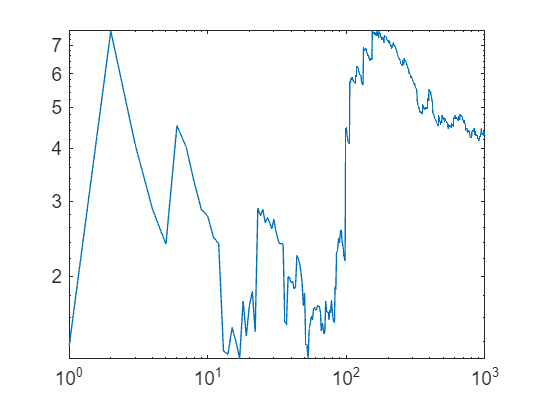

M = 10^3;
I = 40;
reference_solution = -2.243320245476691e+02;
ref_var = 7.321607988889145e+05;

u_h = zeros([M I+1]);
u_h2 = zeros([M 2*I+1]);
samples_h = zeros([M 1]);
samples_h2 = zeros([M 1]);
MC_est_h = zeros([M 1]);
MC_var_h = zeros([M 1]);
MC_est_h2 = zeros([M 1]);
MC_var_h2 = zeros([M 1]);
bias = zeros([M 1]);

for k=1:M
    u_h(k, :) = FEM(I/2, randomfieldtype);
    u_h2(k, :) = FEM(I, randomfieldtype);
    samples_h(k) = h*sum(u_h(k,:));
    samples_h2(k) = h*sum(u_h2(k,:));
end

for k=1:M
    MC_est_h(k) = 1/k*sum(samples_h(1:k));
    MC_est_h2(k) = 1/k*sum(samples_h2(1:k));
    if k>1
        MC_var_h(k) = 1/(k-1)*sum((samples_h(1:k) - MC_est_h(k)).^2);
        MC_var_h2(k) = 1/(k-1)*sum((samples_h2(1:k) - MC_est_h2(k)).^2);
    end
    bias(k) = abs(MC_est_h(k) - MC_est_h2(k))/abs(-12.2462011077315);
end

loglog(1:M, bias)